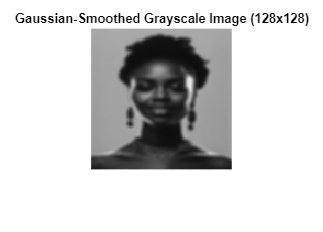


% rgb to grayscale for Canny Filter and Applying Gaussian Smoothing


clear; close all; clc;

% === Step 1: Load and preprocess the image ===
img = imread('queen4.jpg');                     % Load RGB image
resized_img = imresize(img, [128, 128]);        % Resize to 128x128
gray_img = rgb2gray(resized_img);               % Convert to grayscale

% === Step 2: Apply Gaussian smoothing ===
gaussian_kernel = fspecial('gaussian', [5 5], 1.6);  % 5x5 kernel, sigma = 1.4
smoothed_img = imfilter(double(gray_img), gaussian_kernel, 'replicate');  % Convert to double for filter

% Optional: Convert smoothed image back to uint8 for export
smoothed_uint8 = uint8(smoothed_img);

% === Step 3: Display smoothed image ===
imshow(smoothed_uint8);
title('Gaussian-Smoothed Grayscale Image (128x128)');


% === Step 4: Flatten to 1D vector (row-major order) ===
pixel_values = reshape(smoothed_uint8, 1, []);

% Debug: Show first few values
disp('First few pixel values after Gaussian smoothing:');

First few pixel values after Gaussian smoothing:


disp(pixel_values(1:30));

   169   168   168   167   167   167   168   167   167   167   166   166   165   165   165   165   164   164   164   164   164   164   164   164   164   163   163   162   162   162




% === Step 5: Save to CSV for Verilog input ===
writematrix(pixel_values, 'flattened_image_128x128.csv');
